# Avance 2: Reto

**Equipo 6:**

- Fernanda Monserrat Galván Romero

- Ivana Renée Carmona Limón

- Jorge Daniel Cruz Case

**Ecuaciones utilizadas**


$$F_{x\;} =\frac{-dU_B }{\textrm{dx}}$$



$$U_{B\;} =-\mu *B$$



$$\mu \equiv I*a^2$$



$$B_x =\frac{\mu_0 \;a^2 I}{2{\left(a^2 +x^2 \right)}^{\frac{3}{2}} }$$



$$U_B =\frac{-\mu {*\mu }_0 *a^2 I}{2{\left(a^2 +x^2 \right)}^{\frac{3}{2}} }\longrightarrow \;$$

$$\frac{-dU_B }{\textrm{dx}}=\frac{3a^2 \mu {I\mu }_0 x}{2{\left(a^2 +x^2 \right)}^{\frac{5}{2}} }\;$$



$$F_x =\frac{3a^2 \mu {I\mu }_0 x}{2{\left(a^2 +x^2 \right)}^{\frac{5}{2}} }\;\;\left(\textrm{ecuación}\;\textrm{de}\;\textrm{la}\;\textrm{fem}\right)$$



$$I=\frac{\varepsilon }{R}$$



$$F_x \;=\;\frac{3a^2 \mu {\;\;\mu }_0 x}{2{R\left(a^2 +x^2 \right)}^{\frac{5}{2}} }\varepsilon$$



$$a_x =-g+\frac{27\;a^6 \;S\;x^3 \mu^3 {\mu_0 }^2 \;v^2 }{8m\;R^2 {\left(x^2 +a^2 \right)}^{\frac{15}{2}} }$$


clear vars;
clf;
set(gcf, 'Position', get(0,'Screensize')); warning('off','all');


**Valores iniciales**

%Permeabilidad del espacio
miu0 = 4*pi*(10^-7);

%miu_0 al cubo
miu_3 = miu0^3;

%masa del imán(kg)
masa = 0.01;  

%Radio del imán (m)
radio = 2;                  
radio_2 = radio^2;
radio_6 = radio^6;

%área del imán (m^2)
area = pi*radio^2;               

%Resistencia
resis = 0.0009; 


%Gravedad
g = 9.81; 

%Miu
U = 1000000;             
U2 = U^2;

%Poscición inicial
x0 = 60;
dt = 0.01; 
h = dt;

%Velocidad inicial
v0 = 0;

%Valores del tiempo
t0 = 0;
tf = 6;


fi0 = 0;
xplot=t0:h:tf;
yplot = 0.*xplot;


**Ecuaciones de la aceleración**

a = @(x) -g + (27*(x^3)*area*(miu_3)*(U2)*(radio_6)*(v0^2))/(8*masa*(resis^2)*(x^2+radio_2)^(15/2));

a0 = -g + (27*(x0^3)*area*(miu_3)*(U2)*(radio_6)*(v0^2))/(8*masa*(resis^2)*(x0^2+radio_2)^(15/2));


**Ecuación de la *****fem *****inducida**

f = @(x) (3*miu0*area*U*(radio_2)*(x)*(v0))/(2*(x^2 + radio_2)^(5/2));

f0 = (3*miu0*area*U*(radio_2)*(x0)*(v0))/(2*(x0^2 + radio_2)^(5/2));

**Vectores de aceleración, velocidad, poscición tiempo**

%Rango de tiempo utilizado
t = t0:h:tf;

%Vectores
vec_pos = zeros(1,length(t));
vec_vel = vec_pos;
vec_area = vec_pos;
vec_tiempo = vec_pos;
vec_fem = vec_pos;

%Datos en la posición 1 del vector
vec_area(1) = a0;
vec_vel(1) = v0;
vec_pos(1) = x0;
vec_tiempo(1) = t0;
vec_fem(1) = fi0;


**Runge Kutta de 4° orden**

for i = 1:(length(t)-1)
    
    k1 = -g + (27*(vec_pos(i)^3)*area*miu_3*U2*(radio_6)*(vec_vel(i)^2))/(8*masa*(resis^2)*(vec_pos(i)^2 + radio_2)^(15/2));
    k2 = -g + (27*((vec_pos(i)+0.5*h)^3)*area*miu_3*U2*(radio_6)*(vec_vel(i)^2))/(8*masa*(resis^2)*((vec_pos(i)+0.5*h)^2 + radio_2)^(15/2));
    k3 = -g + (27*((vec_pos(i)+0.5*h)^3)*area*miu_3*U2*(radio_6)*(vec_vel(i)^2))/(8*masa*(resis^2)*((vec_pos(i)+0.5*h)^2 + radio_2)^(15/2));
    k4 = -g + (27*((vec_pos(i)+h)^3)*area*miu_3*U2*(radio_6)*(vec_vel(i)^2))/(8*masa*(resis^2)*((vec_pos(i)+h)^2 + radio_2)^(15/2));

    vec_vel(i+1) = vec_vel(i) + (1/6).*(k1+(2.*k2)+(2.*k3)+k4).*h;

    vec_area(i) = k1;

    l1 = vec_vel(i) + vec_area(i)*dt;
    l2 = vec_vel(i) + vec_area(i)*(dt+0.5*h);
    l3 = vec_vel(i) + vec_area(i)*(dt+0.5*h);
    l4 = vec_vel(i) + vec_area(i)*(dt+h);

    vec_pos(i+1) = vec_pos(i) + (1/6) * (l1 + 2*l2 + 2*l3 + l4) * h;
    
    vec_tiempo(i+1) = vec_tiempo(i) + dt;
    
    
    b1 = (3*miu0*area*U*(radio_2+50)*(vec_pos(i))*(vec_vel(i)))/(2*(vec_pos(i)^2 + radio_2+50)^(5/2));
    b2 = (3*miu0*area*U*(radio_2+50)*(vec_pos(i)+0.5*h)*(vec_vel(i)))/(2*((vec_pos(i)+0.5*h)^2 + radio_2+50)^(5/2));
    b3 = (3*miu0*area*U*(radio_2+50)*(vec_pos(i)+0.5*h)*(vec_vel(i)))/(2*((vec_pos(i)+0.5*h)^2 + radio_2+50)^(5/2));
    b4 = (3*miu0*area*U*(radio_2+50)*(vec_pos(i)+h)*(vec_vel(i)))/(2*((vec_pos(i)+h)^2 + radio_2+50)^(5/2));
    
    vec_fem(i+1) = vec_fem(i) + (1/6).*(b1 + 2*b2 + 2*b3 + b4) * h;
    
end


**Graficación de los resultados**

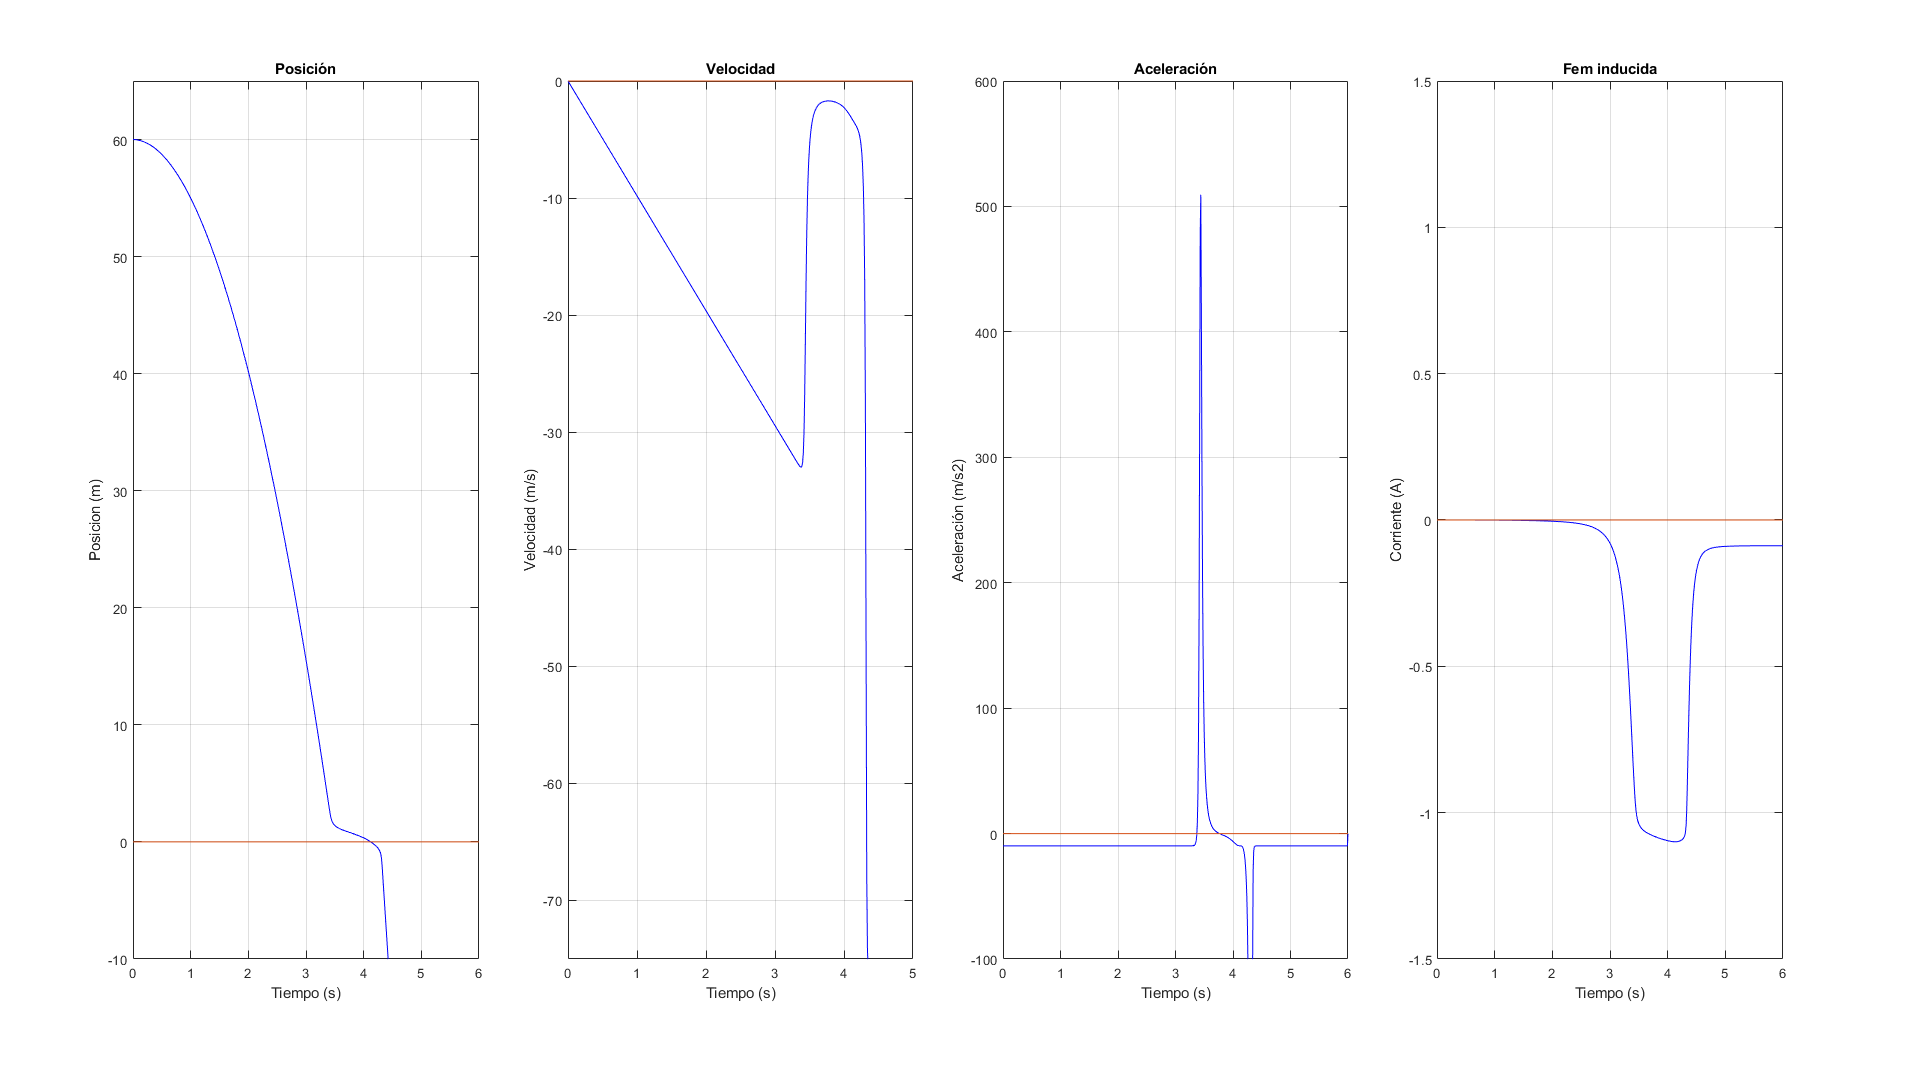

t = tiledlayout(1,4);
nexttile
plot(vec_tiempo,vec_pos,'b')
hold on;
plot(xplot, yplot);
grid on;
axis([t0 tf -10 x0+5]);
title('Posición')
xlabel('Tiempo (s)')
ylabel('Posicion (m)')

nexttile
plot(vec_tiempo,vec_vel,'b')
hold on;
plot(xplot, yplot);
grid on;
axis([t0 tf-1 -75 0]);
title('Velocidad')
xlabel('Tiempo (s)')
ylabel('Velocidad (m/s)')

nexttile
plot(vec_tiempo,vec_area,'b')
hold on;
plot(xplot, yplot);
grid on;
axis([t0 tf -100 600]);
title('Aceleración')
xlabel('Tiempo (s)')
ylabel('Aceleración (m/s2)')

nexttile
plot(vec_tiempo,vec_fem, 'b')
hold on;
plot(xplot, yplot);
grid on;
axis([t0 tf -1.5 1.5]);
title('Fem inducida')
xlabel('Tiempo (s)')
ylabel('Corriente (A)')